# Part 2: 潮流計算

潮流計算は、ある需要と発電の条件のもとで、各母線の電圧と各送電線を流れる電力を求める計算です。この Part では、IEEE 9 母線系統と 2 母線の小さな系統を使って、母線ごとに決める量と求める量、有効電力と無効電力の流れ方、電力方程式とニュートン法を、数式と計算で確かめます。最後に、負荷を増やすと電圧と損失がどう変わり、どこで解けなくなるかを調べます。

**この Part で分かること**

- 潮流計算が求めるもの（ある瞬間の、変わらない運転状態）

- 母線の種類（slack・PV・PQ）ごとに、決めておく 2 つの量と、計算で求める 2 つの量

- 有効電力は位相の差で、無効電力は電圧の大きさの差で流れる理由

- 電力方程式をニュートン法で解く仕組みと、解けないことがある理由

- 結果の読み方と、負荷を増やしたときの電圧と損失の変化。潮流計算が時間シミュレーションの出発点になる理由

知識ページ: [Part 2: 潮流計算](matlab:web("https://guilda-dev.github.io/guilda-doc/lecture/part2-power-flow.html","-browser"))（クリックするとブラウザで開きます）。知識ページの図は、このライブスクリプトを実行すると描けます。

**注意**: 実行する前に、GUILDA のフォルダで `GUILDA` を実行してパスを通しておきます。上のリンクも、このパスから知識ページの場所を求めて開きます。全体の実行には 1〜2 分かかります。

## 0. 図の色

この Part の図は、知識ページと同じ配色で描きます。色を RGB（0〜1）で決めておきます。

sct_color.rr_brand = [0, 89, 167] / 255;    % 青: 主役の量
sct_color.rr_c2    = [46, 107, 63] / 255;   % 緑
sct_color.rr_c3    = [154, 91, 0] / 255;    % 橙: 比べる相手
sct_color.rr_ink2  = [56, 66, 76] / 255;    % 濃い灰色: 軸の線
sct_color.rr_muted = [90, 101, 112] / 255;  % 灰色: 補助の線
sct_color.rr_tint  = [238, 243, 248] / 255; % 淡い青: 範囲の帯

## 1. 潮流は運転状態の「写真」

需要は一日の中で変わり、発電機の出力もそれに合わせて変わります。しかし数分程度の間なら、需要も各発電機の出力もほとんど変わらず、系統は落ち着いた状態にあります。この落ち着いた状態での、各母線の電圧と各送電線を流れる電力の分布を**潮流**といいます。潮流計算は、系統のある瞬間の「写真」を撮るようなものです。一日の需要の変化を模式的な曲線で描き、写真を撮る時刻に印を付けます。

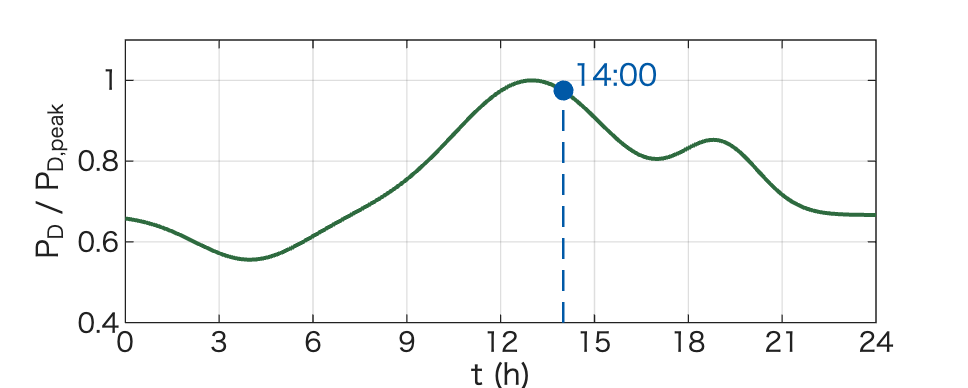

rv_t = linspace(0, 24, 481)';   % [h] 時刻
f_demand = @(t) 0.6 + 0.3 * exp(-((t - 13) / 3.5).^2) + 0.15 * exp(-((t - 19) / 1.8).^2) ...
    - 0.1 * exp(-((t - 4) / 2.5).^2);   % 模式的な需要の曲線（測ったデータではない）
r_peak = max(f_demand(rv_t));
r_t0 = 14;                      % [h] 写真を撮る時刻
r_P0 = f_demand(r_t0) / r_peak;

figure(Position=[100, 100, 900, 360]);
ax = axes(XLim=[0, 24], YLim=[0.4, 1.1], XTick=0:3:24, XGrid="on", YGrid="on", Box="on");
hold(ax, "on");
plot(ax, rv_t, f_demand(rv_t) / r_peak, Color=sct_color.rr_c2, LineWidth=1.5);
plot(ax, [r_t0, r_t0], [0.4, r_P0], "--", Color=sct_color.rr_brand, LineWidth=1);
plot(ax, r_t0, r_P0, "o", MarkerSize=7, MarkerFaceColor=sct_color.rr_brand, MarkerEdgeColor=sct_color.rr_brand);
text(ax, r_t0 + 0.3, r_P0 + 0.04, "14:00", Color=sct_color.rr_brand);
xlabel(ax, "t (h)");
ylabel(ax, "P_D / P_{D,peak}");

曲線は一日のピークを 1 とした模式的なものです。潮流計算は、ある時刻（ここでは 14:00）の需要と発電に対する落ち着いた状態を求めます。この「写真」を見ると、計画した運転で電圧が範囲内に収まっているか、容量を超えて電力が流れる送電線がないかが分かります。一日のピーク、夜間、送電線を 1 本止めたときなど、いろいろな条件でこの確認を繰り返します。写真には動きが写らないので、事故のように条件が急に変わったときに何が起きるかは、時間シミュレーション（Part 3）で調べます。

この Part では、同梱の IEEE 9 母線系統を使います。発電機 3 台と負荷 3 つからなる、小さなベンチマーク系統です。

net = network.IEEE9bus();

## 2. 母線ごとに決める量と求める量

交流では、母線の電圧に大きさ $V$ と位相角 $\theta$ があります。母線からネットワークに注入する電力には、有効電力 $P$ と無効電力 $Q$ があります。つまり母線ごとに 4 つの量があります。ネットワークからは母線ごとに 2 本の式（$P$ の式と $Q$ の式）が得られるので、4 つのうち 2 つを先に決めておき、残りの 2 つを計算で求めます。

- **PQ 母線**: 負荷が使う電力は分かっているので、$P$ と $Q$ を決めます（ネットワークから電力を取り出すので負の値です）。機器のない母線も $P = Q = 0$ の PQ 母線です。

- **PV 母線**: 発電機には出す有効電力が指示され、電圧の調整装置（AVR）が電圧の大きさを一定に保ちます。そのために必要な無効電力は発電機が自然に出すので、$Q$ は計算で求めます。

- **slack 母線**: 損失は計算してみるまで分からないので、すべての発電機の有効電力を先に決めることはできません。そこで 1 つの発電機の母線が残りを引き受け、その $P$ と $Q$ を計算で求めます。この母線の位相角を 0 とし、ほかの母線の位相角の基準にします。

IEEE 9 母線系統の、母線の種類と指定値を表示します。

sct_PFcondition = net.get_pf_condition();

Bus
             Type      Varg      V        P        Q  
            _______    ____    _____    _____    _____

    B001    "slack"      0      1.04      NaN      NaN
    B002    "PV"       NaN     1.025     1.63      NaN
    B003    "PV"       NaN     1.025     0.85      NaN
    B004    "PQ"       NaN       NaN        0        0
    B005    "PQ"       NaN       NaN    -1.25     -0.5
    B006    "PQ"       NaN       NaN     -0.9     -0.3
    B007    "PQ"       NaN       NaN        0        0
    B008    "PQ"       NaN       NaN       -1    -0.35
    B009    "PQ"       NaN       NaN        0        0



`Type` が母線の種類で、B001 が slack 母線、B002 と B003 が PV 母線、残りが PQ 母線です。`NaN` の欄は指定せず、計算で求める量です。未知数は、slack 以外の 8 母線の位相角と PQ 母線 6 つの電圧の大きさで 14 個です。

**注意**: slack 母線は利用者が選びます（`net.a_Bus{1}.l_isSlack = true` のように指定します）。GUILDA が自動で選ぶことはありません。表を表示せずに受け取るだけなら `net.get_pf_condition(Display=false)` とします。

## 3. 有効電力は位相差で、無効電力は電圧差で流れる

2 つの母線を 1 本の送電線でつないだ場合を考えます。送電線はほとんどがインダクタンスの性質を持つので、抵抗を無視し、リアクタンス $X$ だけを考えます。2 つの母線の電圧の大きさを $V_1$、$V_2$、位相角を $\theta_1$、$\theta_2$ とすると、母線 1 から母線 2 に送られる有効電力と、母線 2 に届く無効電力は次の式になります（抵抗がないので有効電力の損失はありません）。


$$P = \frac{V_1 V_2}{X}\,\sin\delta, \qquad Q_2 = \frac{V_1 V_2 \cos\delta - V_2^2}{X}, \qquad \delta = \theta_1 - \theta_2$$


この式を GUILDA の潮流計算で確かめます。母線 1 の発電機が 1.2 pu を送り出し、母線 2 の発電機（slack 母線）が受け取る 2 母線の系統を組み立てます。送電線は $X = 0.5$ pu、抵抗と対地容量は 0 で、両方の母線の電圧の大きさを 1 pu に保ちます。

net2 = PowerNetwork("TwoBus");
net2.add_bus(V=1.0, X=0, Y=0);
net2.add_bus(V=1.0, Varg=0, X=1, Y=0);
net2.add_branch("pi", [1,2], R=0, X=0.5, C=0);
net2.a_Bus{1}.add_component("gen-classical", P=1.2);
net2.a_Bus{2}.add_component("gen-classical", P=0);
net2.a_Bus{2}.l_isSlack = true;

INFO: ' B002 '  set as slack bus.
      P and Q specifications for ' B002SG1 ' ignored in powerflow calculation.


res2 = net2.calculate_powerflow(Progress="none");
res2.tab_bus(:, ["Varg", "V", "P", "Q"])

ans = 2×4 table
             Varg     V     P       Q 
            ______    _    ____    ___

    B001    0.6435    1     1.2    0.4
    B002         0    1    -1.2    0.4


母線 1 は PV 母線なので $P = 1.2$ pu と $V_1 = 1$ pu が決まり、位相角が求まりました。結果から $\delta$ を求め、上の 2 つの式に代入した値と、潮流計算の値を比べます（母線 2 に届く無効電力は、ブランチの受け取り側の値 `Qto` の符号を変えたものです）。

r_X = 0.5;
r_delta = res2.tab_bus.Varg(1) - res2.tab_bus.Varg(2);   % [rad]
r_V1 = res2.tab_bus.V(1);
r_V2 = res2.tab_bus.V(2);
rr_P  = [res2.tab_branch.Pfrom(1), r_V1 * r_V2 / r_X * sin(r_delta)]                % [pu] P: 潮流計算、式

rr_P =     1.2000    1.2000


rr_Q2 = [-res2.tab_branch.Qto(1), (r_V1 * r_V2 * cos(r_delta) - r_V2^2) / r_X]     % [pu] Q2: 潮流計算、式

rr_Q2 =    -0.4000   -0.4000


rad2deg(r_delta)

ans = 36.8699

2 つは一致し、位相差は $\delta = \arcsin(1.2 \times 0.5) = 36.87\degree $ です。有効電力は、位相が進んだ母線から遅れた母線に流れ、位相差が大きいほど多く流れます。一方、電圧の大きさが等しくても $Q_2 = -0.4$ pu と負になりました。位相差が大きいと送電線のリアクタンスそのものが無効電力（$X|I|^2$）を消費し、その分を両端の母線が出す必要があるためです。

2 つの式を、位相差と電圧の大きさを変えて描きます。左は $V_1 = V_2 = 1$ pu での $P$ と $\delta$ の関係、右は $\delta = 0\degree , 10\degree , 20\degree $ での $Q_2$ と $V_1$ の関係です。

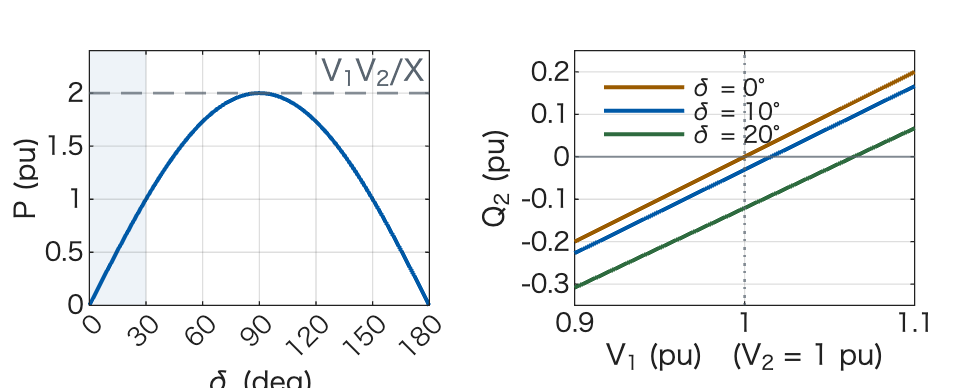

r_V2 = 1;                            % [pu] 母線 2 の電圧
rv_delta = linspace(0, 180, 361)';   % [deg]
rv_V1 = linspace(0.9, 1.1, 101)';    % [pu]
rr_delta_q = [0, 10, 20];            % [deg]

figure(Position=[100, 100, 900, 360]);
tl = tiledlayout(1, 2, TileSpacing="loose", Padding="compact");
ax = nexttile(tl);
set(ax, XLim=[0, 180], YLim=[0, 2.4], XTick=0:30:180, XGrid="on", YGrid="on", Box="on");
hold(ax, "on");
patch(ax, [0, 30, 30, 0], [0, 0, 2.4, 2.4], sct_color.rr_tint, EdgeColor="none");
plot(ax, rv_delta, 1 * r_V2 / r_X * sind(rv_delta), Color=sct_color.rr_brand, LineWidth=1.5);
yline(ax, r_V2 / r_X, "--", "V_1V_2/X", Color=sct_color.rr_muted, LineWidth=1, LabelHorizontalAlignment="right");
xlabel(ax, "δ (deg)");
ylabel(ax, "P (pu)");
ax.Layer = "top";

ax = nexttile(tl);
set(ax, XLim=[0.9, 1.1], YLim=[-0.35, 0.25], XGrid="on", YGrid="on", Box="on");
hold(ax, "on");
rm_qColor = [sct_color.rr_c3; sct_color.rr_brand; sct_color.rr_c2];
for i_d = 1:numel(rr_delta_q)
    rv_Q2 = (rv_V1 * r_V2 * cosd(rr_delta_q(i_d)) - r_V2^2) / r_X;
    plot(ax, rv_V1, rv_Q2, Color=rm_qColor(i_d, :), LineWidth=1.5, DisplayName=sprintf("δ = %d°", rr_delta_q(i_d)));
end
yline(ax, 0, Color=sct_color.rr_muted, LineWidth=0.8, HandleVisibility="off");
xline(ax, r_V2, ":", Color=sct_color.rr_muted, LineWidth=1, HandleVisibility="off");
xlabel(ax, "V_1 (pu)   (V_2 = 1 pu)");
ylabel(ax, "Q_2 (pu)");
legend(ax, Location="northwest", Box="off");

左の図から、有効電力が位相差とともに増えるのは 90° までで、送電線は $V_1V_2/X$ より多くの有効電力を送れないことが分かります。送電線が長い（$X$ が大きい）ほど、また電圧が低いほど、この限界は小さくなります。ふだんの運転は、位相差の小さい範囲（色の付いた帯）で行います。

右の図では、$Q_2$ はほぼ電圧の差 $V_1 - V_2$ に比例し、位相差を変えても曲線が少しずれるだけです。位相差が小さいときは $\cos\delta \approx 1$（$|\delta| \le 10\degree $ なら 0.98 以上）なので、近似的に次の式になります。


$$Q_2 \approx \frac{V_2}{X}\,(V_1 - V_2) \qquad (\cos\delta \approx 1)$$


無効電力は電圧の高い母線から低い母線に流れます。逆にいえば、無効電力を多く使う母線では電圧が下がります。送電網では「$P$ は位相差、$Q$ は電圧差で流れる」と覚えておくとよく、これは送電線がほぼリアクタンスだけで、位相差が小さいから成り立つ関係です。抵抗の大きい配電線では、あまり当てはまりません。

## 4. 電力方程式とニュートン法

### 4.1 電力方程式

$n$ 母線の系統で、母線 $i$ からネットワークに流れ出す電力は、すべての母線の電圧と、母線アドミタンス行列（$I = YV$）の要素 $Y_{im} = G_{im} + jB_{im}$ で決まります。複素電力で書くと $P_i + jQ_i = V_i \overline{I_i} = V_i \sum_m \overline{Y_{im} V_m}$ で、実部と虚部に分けたものが**電力方程式**です。


$$P_i(V, \theta) = \sum_{m=1}^{n} V_i V_m \left( G_{im} \cos\theta_{im} + B_{im} \sin\theta_{im} \right), \qquad Q_i(V, \theta) = \sum_{m=1}^{n} V_i V_m \left( G_{im} \sin\theta_{im} - B_{im} \cos\theta_{im} \right)$$


ここで $\theta_{im} = \theta_i - \theta_m$ です。IEEE 9 母線系統の潮流計算を実行し、その解の電圧と $Y$ を上の式に代入して、結果の $P$・$Q$ と一致することを確かめます。

[result, flag] = net.calculate_powerflow();
flag

flag = 1

cm_Y = net.get_admittance_matrix().Variables;
cv_V = result.tab_bus.Vphasor;          % [pu] 母線電圧のフェーザ
cv_S = cv_V .* conj(cm_Y * cv_V);       % P + jQ（電力方程式を複素数で計算）
max(abs([real(cv_S) - result.tab_bus.P, imag(cv_S) - result.tab_bus.Q]), [], "all")

ans = 0

`flag` が 1 なら収束しています。式から計算した $P$・$Q$ と結果の値の差は、丸めの大きさです。解では、この $P_i$、$Q_i$ が各母線で決めた電力 $P_i^\mathrm{spec}$、$Q_i^\mathrm{spec}$ に等しくなければなりません。その差を**不平衡量**（ミスマッチ）といいます。


$$\Delta P_i = P_i^\mathrm{spec} - P_i(V, \theta), \qquad \Delta Q_i = Q_i^\mathrm{spec} - Q_i(V, \theta)$$


式は slack 以外の母線の $\Delta P_i = 0$ と PQ 母線の $\Delta Q_i = 0$ で、未知数と同じ 14 本です。電圧どうしの積や位相角の sin・cos を含む非線形の式なので、一度では解けません。電圧を仮に決め、不平衡量を測り、仮の値を直す、という手順を繰り返して解きます。

**注意**: 計算方法の既定はニュートン法（`Solver="newton"`）、許容値の既定は `Tolerance=1e-8` です。`net.calculate_powerflow(Solver="levenberg-marquardt")` のように、その呼び出しだけ変えられます。潮流計算はモデル `net` を書き換えず、結果はすべて `result` に入ります。

### 4.2 ニュートン法を 1 変数で

仮の値の直し方として標準的なのが**ニュートン法**（ニュートン・ラフソン法）です。未知数が 1 つ $x$ で、0 にしたい不平衡量が $f(x)$ だとします。今の仮の値で曲線の接線を引き、接線が 0 になる点に移ります。


$$x_{k+1} = x_k - \frac{f(x_k)}{f'(x_k)}$$


3 節の 2 母線の送電線（$V_1 = V_2 = 1$ pu、$X = 0.5$ pu）で、未知数を $x = \delta$、不平衡量を $f(\delta) = (V_1V_2/X)\sin\delta - P^\mathrm{spec}$（$P^\mathrm{spec} = 1.2$ pu）として、$\delta_0 = 60\degree $ から 5 回反復します。

r_Pmax = 1 * 1 / 0.5;                   % [pu] V1 V2 / X
r_Pspec = 1.2;                          % [pu]
f_mis = @(d) r_Pmax * sin(d) - r_Pspec; % 不平衡量（d は rad）
f_slope = @(d) r_Pmax * cos(d);         % その傾き
n_step = 5;
rv_d = zeros(n_step + 1, 1);
rv_d(1) = deg2rad(60);
for i_step = 1:n_step
    rv_d(i_step + 1) = rv_d(i_step) - f_mis(rv_d(i_step)) / f_slope(rv_d(i_step));
end
r_dsol = asin(r_Pspec / r_Pmax);        % 解 δ*
fprintf("k = %d: δ_k = %8.4f°、|δ_k − δ*| = %.2e°\n", [(0:n_step); rad2deg(rv_d.'); abs(rad2deg(rv_d.' - r_dsol))]);

k = 0: δ_k =  60.0000°、|δ_k − δ*| = 2.31e+01°
k = 1: δ_k =  29.5157°、|δ_k − δ*| = 7.35e+00°
k = 2: δ_k =  36.5829°、|δ_k − δ*| = 2.87e-01°
k = 3: δ_k =  36.8694°、|δ_k − δ*| = 5.35e-04°
k = 4: δ_k =  36.8699°、|δ_k − δ*| = 1.87e-09°
k = 5: δ_k =  36.8699°、|δ_k − δ*| = 0.00e+00°


誤差は 1 回目で 7° ほどに、2 回目で 0.3° 以下になり、その先は反復ごとにおよそ 2 乗になって、正しい桁数がほぼ倍に増えます。最初の 2 歩を図にします。

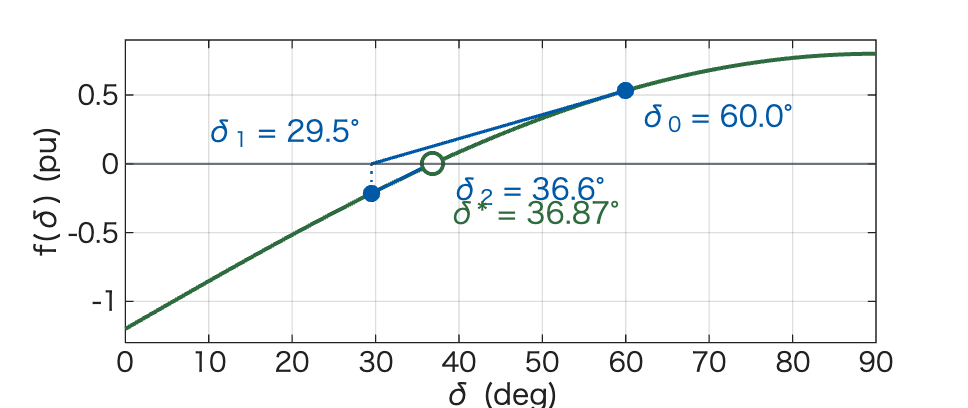

rv_dplot = linspace(0, deg2rad(90), 301)';
figure(Position=[100, 100, 900, 380]);
ax = axes(XLim=[0, 90], YLim=[-1.3, 0.9], XTick=0:10:90, XGrid="on", YGrid="on", Box="on");
hold(ax, "on");
yline(ax, 0, Color=sct_color.rr_ink2, LineWidth=0.8);
plot(ax, rad2deg(rv_dplot), f_mis(rv_dplot), Color=sct_color.rr_c2, LineWidth=1.5);
for i_step = 1:2
    r_d = rv_d(i_step);
    rv_dline = linspace(rv_d(i_step + 1), r_d, 2);
    plot(ax, rad2deg(rv_dline), f_mis(r_d) + f_slope(r_d) * (rv_dline - r_d), Color=sct_color.rr_brand, LineWidth=1.2);
    plot(ax, rad2deg([rv_d(i_step + 1), rv_d(i_step + 1)]), [0, f_mis(rv_d(i_step + 1))], ":", ...
        Color=sct_color.rr_brand, LineWidth=1);
end
plot(ax, rad2deg(rv_d(1:3)), f_mis(rv_d(1:3)), "o", MarkerSize=6, MarkerFaceColor=sct_color.rr_brand, ...
    MarkerEdgeColor=sct_color.rr_brand);
plot(ax, rad2deg(r_dsol), 0, "o", MarkerSize=8, MarkerFaceColor="w", MarkerEdgeColor=sct_color.rr_c2, LineWidth=1.5);
rm_pos = [rad2deg(rv_d(1)) + 1.2, f_mis(rv_d(1)) - 0.06; rad2deg(rv_d(2)) - 1.2, 0.08; rad2deg(r_dsol) + 1.8, -0.06];
sr_valign = ["top", "bottom", "top"];
sr_halign = ["left", "right", "left"];
for i_step = 1:3
    text(ax, rm_pos(i_step, 1), rm_pos(i_step, 2), sprintf("δ_%d = %.1f°", i_step - 1, rad2deg(rv_d(i_step))), ...
        VerticalAlignment=sr_valign(i_step), HorizontalAlignment=sr_halign(i_step), Color=sct_color.rr_brand);
end
text(ax, rad2deg(r_dsol) + 1.8, -0.25, sprintf("δ* = %.2f°", rad2deg(r_dsol)), VerticalAlignment="top", Color=sct_color.rr_c2);
xlabel(ax, "δ (deg)");
ylabel(ax, "f(δ) (pu)");

曲線が直線に近い範囲では、接線をたどるだけで解のすぐ近くに着きます。逆に、接線が水平に近い所（$\delta$ が 90° に近い所）から始めると、接線が 0 になる点は遠くに飛び、うまく収束しません。この 2 母線の例では、$P^\mathrm{spec}$ が $V_1V_2/X = 2$ pu を超えると曲線が 0 に届かず、解がありません。

### 4.3 多変数のニュートン法とヤコビ行列

実際の系統では、未知数は位相角と電圧の大きさで、傾き $f'$ は**ヤコビ行列**（ヤコビアン）$J$ という行列になります。電圧や位相角を少し変えたとき、各母線の電力がどれだけ変わるかを並べた行列です。1 回の反復ごとに、今の仮の値で計算したこの行列を使って連立一次方程式を 1 つ解き、その解を足します。


$$\underbrace{\left[\begin{array}{cc} \partial P / \partial \theta & \partial P / \partial V \\ \partial Q / \partial \theta & \partial Q / \partial V \end{array}\right]}_{J(\theta_k, V_k)} \left[\begin{array}{c} \Delta\theta \\ \Delta V \end{array}\right] = \left[\begin{array}{c} \Delta P(\theta_k, V_k) \\ \Delta Q(\theta_k, V_k) \end{array}\right], \qquad \left[\begin{array}{c} \theta_{k+1} \\ V_{k+1} \end{array}\right] = \left[\begin{array}{c} \theta_k \\ V_k \end{array}\right] + \left[\begin{array}{c} \Delta\theta \\ \Delta V \end{array}\right]$$


$\theta$、$V$、$\Delta P$、$\Delta Q$ は未知数と不平衡量を並べたベクトル、$k$ は反復の回数です。未知数と式が 1 つずつなら、$\Delta P = -f$ なので 4.2 の接線の一歩と同じです。最初の仮の値には、すべての位相角を 0、電圧の大きさを 1 pu（指定のある母線はその値）とする**フラットスタート**がよく使われます。

IEEE 9 母線系統をフラットスタートから解き直し（`WarmStart=false`）、反復ごとの不平衡量の最大値を GUILDA の `plot_convergence` で描きます。

[resultFlat, flag] = net.calculate_powerflow(WarmStart=false);
resultFlat.output

ans = フィールドをもつ struct:
    iterations: 4
     algorithm: "newton"
      residual: 6.1617e-15
       message: '✔ The Newton-Raphson iteration has converged within the tolerance limit (4 iterations).'


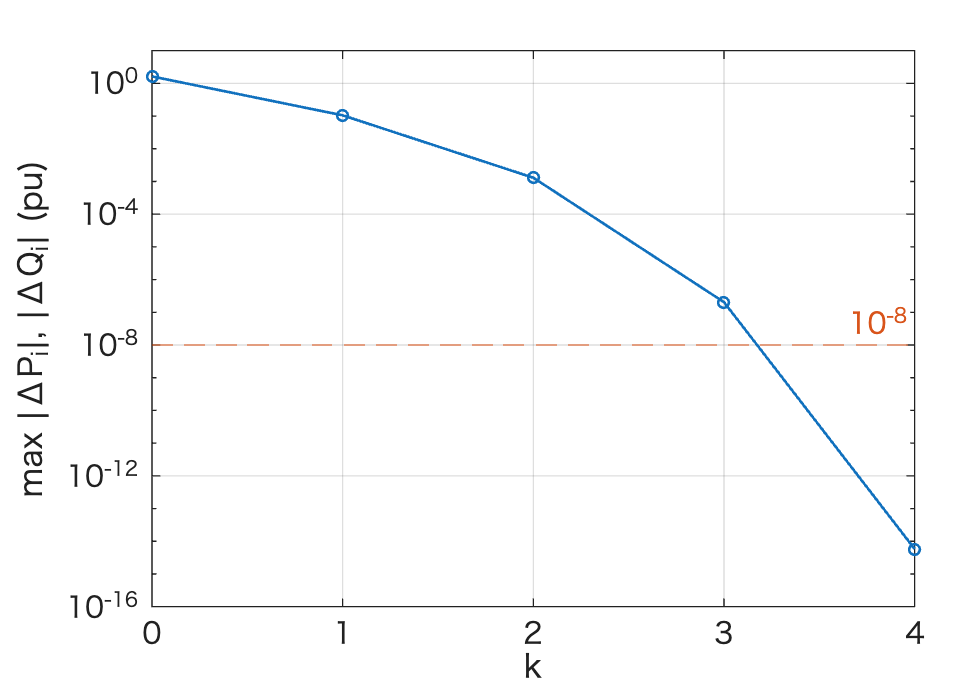

figure(Position=[100, 100, 560, 400]);
ax = nexttile(tiledlayout(1, 1, Padding="compact"));
resultFlat.plot_convergence(Parent=ax);
title(ax.Parent, "");
set(findall(ax, "Type", "ConstantLine"), Label="10^{-8}");   % 許容値の線
xlabel(ax, "k");
ylabel(ax, "max |ΔP_i|, |ΔQ_i| (pu)");
set(ax, YLim=[1e-16, 10], YTick=10.^(-16:4:0), YMinorGrid="off", XGrid="on", YGrid="on", Box="on");

縦軸は対数目盛です。4 回の反復で許容値 $10^{-8}$ pu（破線）を下回りました。結果には反復ごとの電圧（`cm_Vhistory`）が残っているので、4.1 の電力方程式で不平衡量を自分で計算して、図の値を確かめます。

sct_cond = resultFlat.tab_PFcondition;
lv_P = sct_cond.Type ~= "slack";        % ΔP の式がある母線
lv_Q = sct_cond.Type == "PQ";           % ΔQ の式がある母線
rv_mis = zeros(numel(resultFlat.rv_step), 1);
for k = 1:numel(resultFlat.rv_step)
    cv_Vk = resultFlat.cm_Vhistory(:, k);
    cv_Sk = cv_Vk .* conj(resultFlat.cm_Y * cv_Vk);
    rv_mis(k) = max(abs([sct_cond.P(lv_P) - real(cv_Sk(lv_P)); sct_cond.Q(lv_Q) - imag(cv_Sk(lv_Q))]));
end
fprintf("k = %d: 最大の不平衡量 %.2e pu\n", [resultFlat.rv_step(:).'; rv_mis.']);

k = 0: 最大の不平衡量 1.63e+00 pu
k = 1: 最大の不平衡量 1.05e-01 pu
k = 2: 最大の不平衡量 1.30e-03 pu
k = 3: 最大の不平衡量 2.04e-07 pu
k = 4: 最大の不平衡量 5.79e-15 pu


最大の不平衡量は 1 pu 程度から始まり、$10^{-1}$、$10^{-3}$、$10^{-7}$ の程度へと、指数がほぼ倍ずつ小さくなって、最後は丸めの大きさになります。解の近くで誤差が反復ごとに 2 乗になる、ニュートン法の性質です。

**注意**

- `WarmStart=false` で、前の解を使わずにフラットスタートから解きます。既定の `true` では、同じ母線の系統で最後に収束した解から始めます。`network.IEEE9bus()` は作るときに一度潮流計算を解いているので、4.1 の計算は反復 0 回で終わっています。

- `PlotFcn="residual"` を指定すると計算の途中の不平衡量をライブで表示し、`Verbose=true` で反復ごとの経過を表示します。

## 5. 結果の読み方

IEEE 9 母線系統（WSCC 9 母線系統とも呼ばれます）は、母線 1 が slack 母線、母線 2 と 3 が PV 母線で、負荷は母線 5、6、8 にあり、母線 4、7、9 には機器がありません。4.1 の結果 `result` を、概要・母線・ブランチの順に読みます。

result.disp_summary();

Power flow of PowerNetwork (Solver newton): converged, flag 1
- Calculation: 0 iterations, largest residual 6.16e-15 pu, elapsed 0.0183 s
- Message: ✔ The Newton-Raphson iteration has converged within the tolerance limit (0 iterations).
- Network: 9 buses (slack 1, PV 2, PQ 6), 9 branches
- Generation: P = 3.1964 pu, Q = 0.2284 pu
- Load: P = 3.1500 pu, Q = 1.1500 pu
- Losses: P = 0.0464 pu, Q = -0.9216 pu
- |V|: max 1.0400 pu at B001, min 0.9956 pu at B005
- Violated operating limits: 0


概要には、母線の数と種類、発電・負荷・損失の合計、電圧の大きさの最大と最小が出ます。母線ごとの値を表と図で見ます。

result.disp_bus();

             Type          Set (pu)         |V| (pu)    Varg (deg)      P (pu)         Q (pu)  
            _______    _________________    ________    __________    ___________    __________

    B001    "slack"    "V=1.04, Varg=0"        1.04            0          0.71641       0.27046
    B002    "PV"       "P=1.63, V=1.025"      1.025         9.28             1.63      0.066537
    B003    "PV"       "P=0.85, V=1.025"      1.025       4.6648             0.85       -0.1086
    B004    "PQ"       "P=0, Q=0"            1.0258      -2.2168      -1.0924e-15    -3.562e-15
    B005    "PQ"       "P=-1.25, Q=-0.5"    0.99563      -3.9888            -1.25          -0.5
    B006    "PQ"       "P=-0.9, Q=-0.3"      1.0127      -3.6874             -0.9          -0.3
    B007    "PQ"       "P=0, Q=0"            1.0258       3.7197      -5.5331e-17    5.7882e-15
    B008    "PQ"       "P=-1, Q=-0.35"       1.0159      0.72754               -1         -0.35
    B009    "PQ"       "P=0, Q=0"      

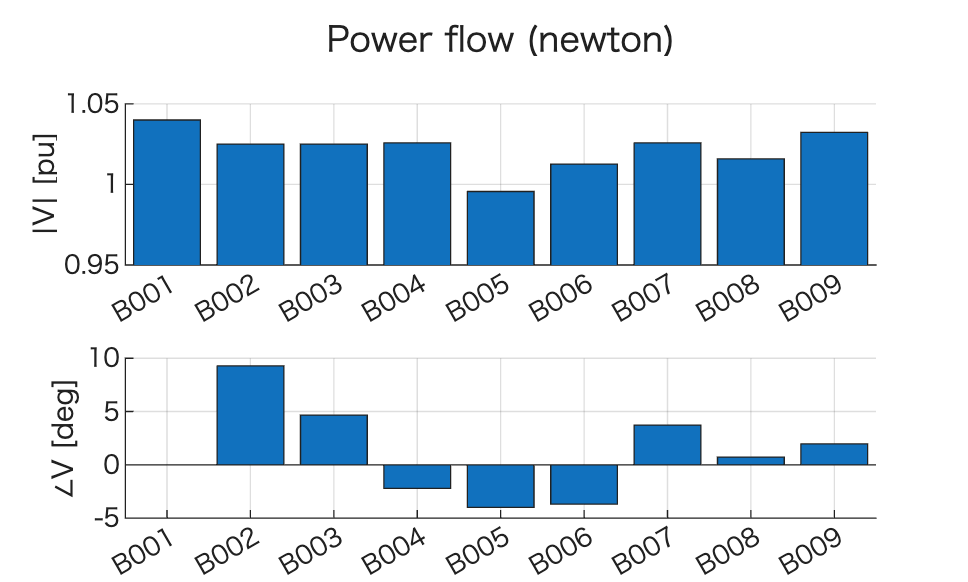

fig = figure;
layout = tiledlayout(fig, 2, 1);
result.plot_voltage(Quantity="magnitude", Limit=false, Parent=nexttile(layout));
ylim([0.95 1.05])
result.plot_voltage(Quantity="angle", Parent=nexttile(layout));

ブランチ（送電線と変圧器）ごとの潮流を表で表示し、系統図の上に電圧と潮流の向きを描きます。母線の色は電圧の大きさ $|V|$、流れの点は有効電力の向きで、点が速いほど多く流れています。

result.disp_branch();

              From       To      Pfrom (pu)    Qfrom (pu)    Pto (pu)    Qto (pu)     Ploss (pu)    Qloss (pu)    Loading
             ______    ______    __________    __________    ________    _________    __________    __________    _______

    ET001    "B001"    "B004"      0.71641        0.27046    -0.71641     -0.23923             0     0.031228       NaN  
    ET002    "B002"    "B007"         1.63       0.066537       -1.63     0.091781             0      0.15832       NaN  
    ET003    "B003"    "B009"         0.85        -0.1086       -0.85      0.14955    1.1102e-16     0.040956       NaN  
    EL004    "B004"    "B005"      0.40937        0.22893     -0.4068     -0.38687     0.0025751     -0.15794       NaN  
    EL005    "B004"    "B006"      0.30704         0.0103    -0.30537     -0.16543     0.0016641     -0.15513       NaN  
    EL006    "B005"    "B007"      -0.8432       -0.11313      0.8662    -0.083808         0.023     -0.19694       NaN  
    EL007    "B006"    

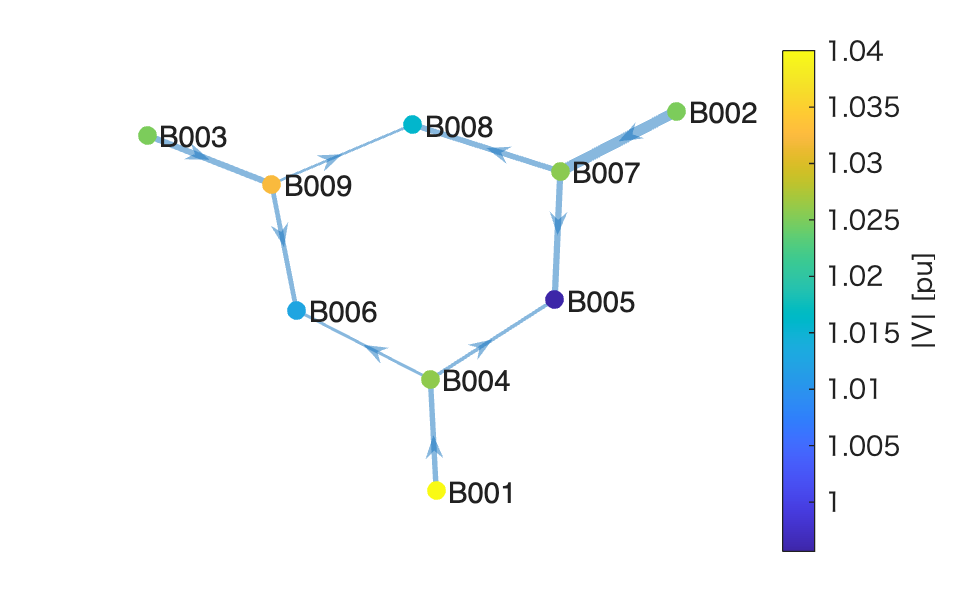

figure(Position=[100, 100, 900, 560]);
ax = nexttile(tiledlayout(1, 1, Padding="compact"));
result.plot_diagram(BusColorMode="V", ColorMode="none", Parent=ax);
title(ax, "");

表と図から、次のことが読み取れます。

- **電圧**: 大きさはすべて 0.996〜1.040 pu の間にあります。PV 母線の B002 と B003 は指定した 1.025 pu で、最も低いのは負荷が最も大きい母線 5（0.996 pu）です。

- **位相角と潮流**: 出力の最も大きい発電機がある母線 2 の位相角が最も大きく（9.28°）、負荷のある母線 5 と 6 は負の位相角（−3.99° と −3.69°）です。母線 2 から母線 7 へは 1.63 pu が流れます。3 節の 2 母線の例のとおり、有効電力は位相角の「坂」を下る向きに流れ、どの矢印も位相角の大きい母線から小さい母線へ向いています。

- **slack 母線**: 発電機 2 と 3 は決めた 1.63 pu と 0.85 pu を出します。発電機 1 は残りの 0.716 pu を出し、負荷（1.25 + 0.90 + 1.00 = 3.15 pu）と損失をまかないます。

- **損失**: 発電の合計は 3.196 pu なので、有効電力の損失は 0.046 pu で、負荷の約 1.5 % です。抵抗が 0 の変圧器（ET001〜ET003）では `Ploss` も 0 です。送電線の `Qloss` が負なのは、対地静電容量の充電電流が出す無効電力が、リアクタンスで消費する無効電力より大きいためです。

**注意**: 表の `Pfrom` は、ブランチの From 側の母線からブランチに流れ込む有効電力で、負の値なら電力は To 側から From 側へ流れています。`result.disp_bus(Unit="SI")` とすると電圧を kV、電力を MW と Mvar で表示します。`result.plot_diagram(FlowMode="Q")` で無効電力の向きを、`result.plot_branch(Quantity="loss")` でブランチごとの損失を描けます。

## 6. 負荷を増やすと：電圧・損失と、収束しないとき

### 6.1 負荷を 1.5 倍にする

3 つの負荷の有効電力と無効電力を、2 節の表の指定値の 1.5 倍にして `net` に書き込み、解き直します。負荷の指定値は、負荷の機器のパラメータの `powerflow` のグループにあります。`get_parameter` で負荷だけを表で取り出し、書き換えて `set_parameter` で書き戻します。

tab_load0 = net.get_parameter("powerflow", Class="component.load.abstract")   % 元の負荷の P、Q

tab_load0 = 3×2 table
                  P        Q  
                _____    _____

    B005LRX1    -1.25     -0.5
    B006LRX1     -0.9     -0.3
    B008LRX1       -1    -0.35


r_scale = 1.5;          % 負荷の倍率
tab_load = tab_load0;
tab_load.P = r_scale * tab_load0.P;
tab_load.Q = r_scale * tab_load0.Q;
net.set_parameter("powerflow", tab_load);
[resultHeavy, flag] = net.calculate_powerflow();
rm_V = [result.tab_bus.V, resultHeavy.tab_bus.V]   % [pu] 列: 負荷 1.0 倍、1.5 倍（行は B001〜B009）

rm_V =     1.0400    1.0400
    1.0250    1.0250
    1.0250    1.0250
    1.0258    1.0024
    0.9956    0.9514
    1.0127    0.9751
    1.0258    1.0063
    1.0159    0.9859
    1.0324    1.0160


r_lossBase  = result.get_summary().r_Ploss

r_lossBase = 0.0464

r_lossHeavy = resultHeavy.get_summary().r_Ploss

r_lossHeavy = 0.0697

前の結果 `result` はモデルを参照しないので、`net` を書き換えても変わりません。電圧を一定に保つ slack 母線と PV 母線（B001〜B003）以外では電圧が下がり、負荷のある B005 は 0.951 pu になりました。負荷を 1.5 倍にすると送電線の電流もおよそ 1.5 倍になり、電圧の低下（$\approx X Q / V$）も、損失（$R|I|^2$）もそれに応じて増えます。損失は 0.046 pu から 0.070 pu に増え、増えた分の有効電力は slack 母線の発電機が引き受けます。

### 6.2 どこまで増やせるか

負荷の倍率 $\lambda$ を 1 から少しずつ増やし、そのつどフラットスタートから解いて、最も低い母線電圧と損失を記録します。解が見つからなかったとき（`flag` が 1 でないとき）の警告は、ここでは止めておきます。

rv_lambda = unique([1:0.05:2.3, 2.3:0.01:2.5]);
rv_Vmin = nan(size(rv_lambda));
rv_loss = nan(size(rv_lambda));
lv_ok = false(size(rv_lambda));
sct_warn = warning("off", "GUILDA:PowerNetwork:PowerflowNotConverged");
for i_lambda = 1:numel(rv_lambda)
    tab_load.P = rv_lambda(i_lambda) * tab_load0.P;
    tab_load.Q = rv_lambda(i_lambda) * tab_load0.Q;
    net.set_parameter("powerflow", tab_load);
    [resultSweep, flagSweep] = net.calculate_powerflow(WarmStart=false, Progress="none");
    lv_ok(i_lambda) = flagSweep == 1;
    if lv_ok(i_lambda)
        sct_sweep = resultSweep.get_summary();
        rv_Vmin(i_lambda) = sct_sweep.r_Vmin;
        rv_loss(i_lambda) = sct_sweep.r_Ploss;
    end
end
warning(sct_warn);
r_last = rv_lambda(find(lv_ok, 1, "last"));
r_fail = rv_lambda(find(~lv_ok, 1));
fprintf("解が求まった最大の倍率 %.2f、解が求まらなかった最初の倍率 %.2f\n", r_last, r_fail);

解が求まった最大の倍率 2.37、解が求まらなかった最初の倍率 2.38


最も低い母線電圧を描き、解が求まらなかった範囲に色を付けます。

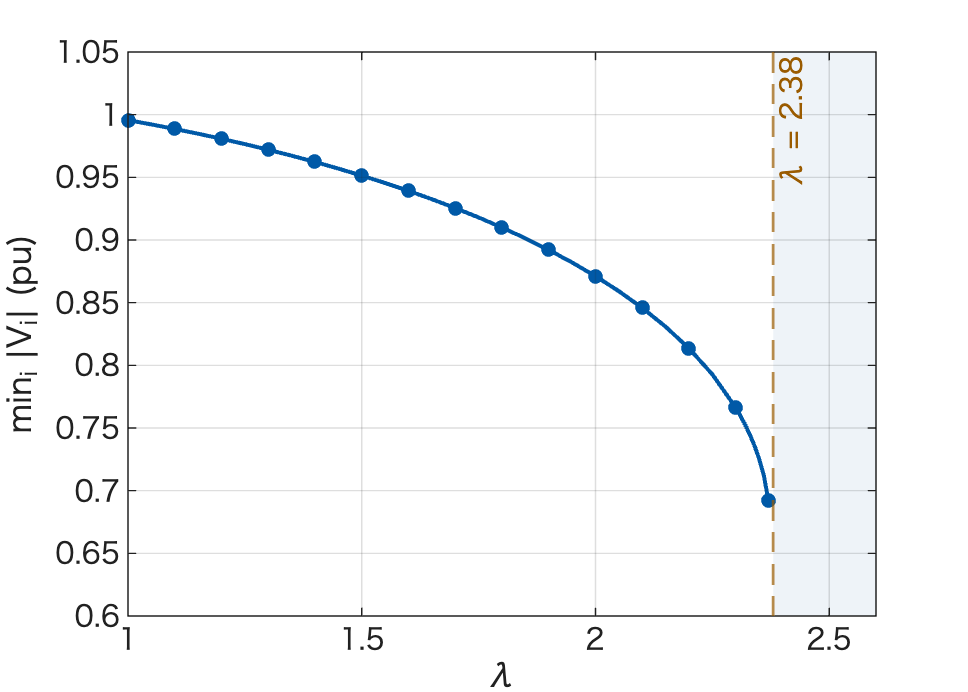

lv_mark = lv_ok & mod(round(rv_lambda * 100), 10) == 0;   % 0.1 刻みの点
figure(Position=[100, 100, 560, 400]);
ax = axes(XLim=[1, 2.6], YLim=[0.6, 1.05], XGrid="on", YGrid="on", Box="on");
hold(ax, "on");
patch(ax, [r_fail, 2.6, 2.6, r_fail], [0.6, 0.6, 1.05, 1.05], sct_color.rr_tint, EdgeColor="none");
xline(ax, r_fail, "--", sprintf("λ = %.2f", r_fail), Color=sct_color.rr_c3, LineWidth=1, ...
    LabelVerticalAlignment="top", LabelHorizontalAlignment="right");
plot(ax, rv_lambda(lv_ok), rv_Vmin(lv_ok), "-", Color=sct_color.rr_brand, LineWidth=1.5);
plot(ax, [rv_lambda(lv_mark), r_last], [rv_Vmin(lv_mark), rv_Vmin(rv_lambda == r_last)], "o", MarkerSize=5, ...
    MarkerFaceColor=sct_color.rr_brand, MarkerEdgeColor=sct_color.rr_brand);
ax.Layer = "top";
xlabel(ax, "λ");
ylabel(ax, "min_i |V_i| (pu)");

最も低い電圧は、負荷を増やすほど下がり方を速め、端の手前で急に折れ曲がります。$\lambda = 2.37$ までは解が求まり、2.38 からは求まりません。ネットワークが送れる以上の電力を負荷が求めると、電力方程式を満たす電圧がそもそも存在しないためです。端の近くではヤコビ行列が特異（逆行列がない状態）に近づき、4.2 の図の接線が水平に近くなって、ニュートン法の一歩が当てにならなくなります。この曲線を先端（ノーズ点）までたどるのが、連続潮流計算（Part 7）です。

損失も描きます。破線は、電流が負荷に比例するとしたときの $\lambda^2$ 倍の目安です。

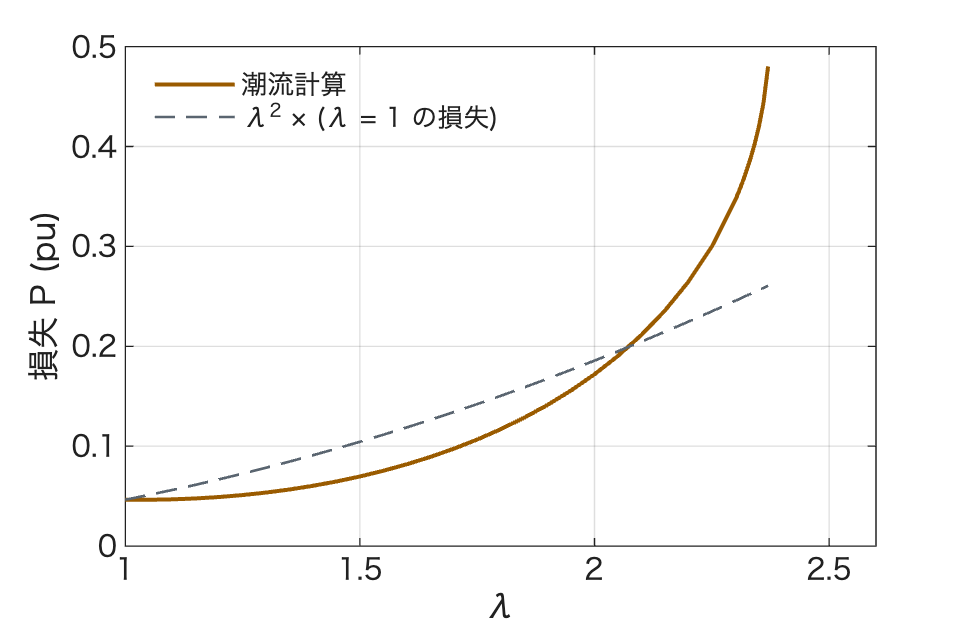

figure(Position=[100, 100, 560, 360]);
ax = axes(XLim=[1, 2.6], XGrid="on", YGrid="on", Box="on");
hold(ax, "on");
plot(ax, rv_lambda(lv_ok), rv_loss(lv_ok), "-", Color=sct_color.rr_c3, LineWidth=1.5, DisplayName="潮流計算");
plot(ax, rv_lambda(lv_ok), rv_loss(1) * rv_lambda(lv_ok).^2, "--", Color=sct_color.rr_muted, LineWidth=1, ...
    DisplayName="λ^2 × (λ = 1 の損失)");
xlabel(ax, "λ");
ylabel(ax, "損失 P (pu)");
legend(ax, Location="northwest", Box="off");

損失は、$\lambda = 2$ くらいまではおよそ $\lambda^2$ の目安に沿って増え、端に近づくと目安を大きく超えて急に増えます。電圧が下がると、同じ電力を送るのにより大きな電流が要る（$|I| \approx P/V$）ので、損失 $R|I|^2$ はさらに増えるためです。負荷が大きいほど、電圧の低下と損失の増加が互いを強め合うことが分かります。

**注意**: 収束したかどうかは、2 番目の出力 `flag` で見分けます。1 なら収束、0 なら反復回数の上限に達した、−2 なら解が見つからなかった、です。`result.l_success` も、収束したときだけ `true` になります。既定では失敗したときに警告が出るので、失敗した結果を知らずに使うことはありません。収束しなかった結果の `tab_bus` などの値は使えません。

ほかによくある収束しない原因は、負荷の符号の間違いや桁違いに大きなリアクタンスといったデータの誤り、slack 母線から切り離されたネットワークの一部、解から遠すぎる最初の仮の値などです。計算が失敗したときは、まずデータと負荷の大きさを確かめるとよいでしょう。

## 7. 時間シミュレーションの出発点

時間シミュレーションは、事故などの外乱の後に系統がどう動くかを計算します。そのためには出発点の状態が必要で、自然な選び方は外乱が起きる前の落ち着いた状態です。それを与えるのが潮流計算です。各発電機の母線の電圧と電流から、発電機の内部の量（回転子の角度、内部の電圧、機械入力）を、何も起きなければ何も動かないように計算します。この状態が**平衡点**です。負荷を元の値に戻し、`initialize` で潮流計算を解いて平衡点を設定します。既定の `WarmStart=true` では、6.2 で最後に収束した解（ノーズ点の近くの解）から計算を始めます。そこから元の負荷の解へはニュートン法が届かないことがありますが、そのときは GUILDA が平らな初期値（フラットスタート）から 1 回だけ解き直すので、そのまま `initialize` できます。

net.set_parameter("powerflow", tab_load0);
net.initialize();
gen2 = net.get_element("B002SG1");
gen2.sv_u.'                  % 入力の名前

ans = 1×2 の string 配列
    "Pmech"    "Vfield"


gen2.rv_Uequilibrium.'       % 平衡点の値

ans =     1.6300    2.8590


母線 2 の発電機の機械入力 `Pmech` の平衡点は、潮流計算で決めた出力 1.63 pu と同じです。損失を除けば、タービンから入る機械入力と送電網へ出す電気出力がつり合っているので、Part 1 の動揺方程式で回転子の速さは変わりません。外乱のないシナリオで 5 秒間計算して、確かめます。

sc = net.add_scenario("steady", Time=[0, 5]);
resultODE = net.simulate("steady", Progress="none");
tab_omega = resultODE.get_trajectory("omega");    % 列: t と各発電機の ω
r_maxOmega = max(abs(tab_omega{:, 2:end}), [], "all")

r_maxOmega = 3.7591e-17

速さのずれは丸めの大きさのままで、系統は平衡点にとどまります。平衡点でない状態から始めると、外乱がなくても系統が動き出してしまい、事故への応答とこの見かけの動きを区別できません。同じ平衡点は、モデルを近似線形化するときの基準の点にもなります（Part 5）。

## まとめ

- 潮流は、ある需要と発電の条件での落ち着いた運転状態で、各母線の電圧と各送電線の電力の分布です。母線ごとの 4 つの量（$V$・$\theta$・$P$・$Q$）のうち 2 つを決め、2 つを求めます。

- 送電網では、有効電力は位相差で（$P = V_1V_2\sin\delta/X$）、無効電力は電圧の大きさの差で流れます。2 母線の潮流計算で、この式を確かめました。

- 電力方程式は、電圧とアドミタンス行列から各母線の $P$ と $Q$ を与えます。潮流計算は、その不平衡量を 0 にする計算です。

- ニュートン法は接線（ヤコビ行列）をたどって仮の値を直し、誤差は反復ごとにおよそ 2 乗になります。IEEE 9 母線系統はフラットスタートから 4 回で収束しました。

- 負荷を増やすと電圧は下がり、損失はおよそ負荷の 2 乗で、解けなくなる端の近くではそれより速く増えます。IEEE 9 母線系統では、負荷を 2.38 倍にすると解が存在しなくなります。収束したかどうかは `flag` で見分けます。

- 潮流計算の結果から平衡点が決まり、時間シミュレーションはそこから始まります。

**次の Part**: Part 3「時間シミュレーション」では、潮流計算で求めた平衡点を出発点にして、事故などの後に系統がどう動くかを計算します。

[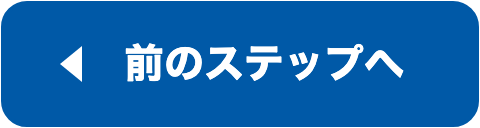](matlab:open('Part1_NetworkComponents.mlx'))　　[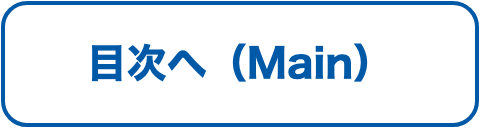](matlab:open('Main.mlx'))　　[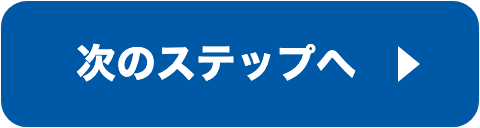](matlab:open('Part3_TimeSimulation.mlx'))